fit1 =      Linear model Poly1:
     fit1(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =       186.9  (183.9, 189.8)
       p2 =      -3.147  (-3.362, -2.932)

fitkwaliteit = struct with fields:
           sse: 0.2396
       rsquare: 0.9993
           dfe: 13
    adjrsquare: 0.9992
          rmse: 0.1358


b = -3.1472

x =          0    0.0010    0.0020    0.0030    0.0040    0.0051    0.0061    0.0071    0.0081    0.0091    0.0101    0.0111    0.0121    0.0131    0.0141    0.0152    0.0162    0.0172    0.0182    0.0192    0.0202    0.0212    0.0222    0.0232    0.0242    0.0253    0.0263    0.0273    0.0283    0.0293    0.0303    0.0313    0.0323    0.0333    0.0343    0.0354    0.0364    0.0374    0.0384    0.0394    0.0404    0.0414    0.0424    0.0434    0.0444    0.0455    0.0465    0.0475    0.0485    0.0495


y =    -3.1472   -2.9584   -2.7696   -2.5809   -2.3921   -2.2034   -2.0146   -1.8259   -1.6371   -1.4483   -1.2596   -1.0708   -0.8821   -0.6933   -0.5045   -0.3158   -0.1270    0.0617    0.2505    0.4392    0.6280    0.8168    1.0055    1.1943    1.3830    1.5718    1.7605    1.9493    2.1381    2.3268    2.5156    2.7043    2.8931    3.0818    3.2706    3.4594    3.6481    3.8369    4.0256    4.2144    4.4031    4.5919    4.7807    4.9694    5.1582    5.3469    5.5357    5.7244    5.9132    6.1020


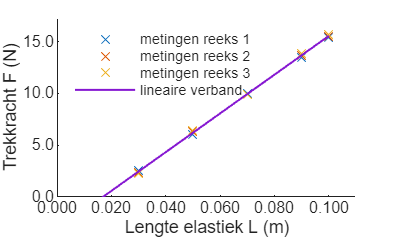

de veerconstante is: 


186.8699N/m


%alles loaden
load lengte.mat

load test1.mat
load test2.mat
load test3.mat

f = [f1; f2; f3];
krachten = [f1 f2 f3];
lSI = l * 0.01;
lSItotaal = [lSI lSI lSI];
figure(1)
hold on

vc = 0;
%for loop voor alle metingen te plotten
legends = {};
for j=1:3
    
    kracht = f(j,:);
    scatter(lSI,kracht,'x')
    legends = [legends {"metingen reeks " + j}];
end
%fitted curve
[fit1, fitkwaliteit] = fit(lSItotaal',krachten',"poly1")
a = fit1.p1;
b = fit1.p2
x = linspace(0,max(lSI))
y = a*x + b
plot(x,y, LineWidth=1)

legends = [legends {"lineaire verband"}];


%plot settings
ax = gca;
xtickformat('%.3f');
ytickformat('%.1f' );
ax.FontSize = 8;
xlim([0 , lSI(end) + 0.01]);
ylim([0 max(krachten)*1.1])
legend(legends)
xlabel('Lengte elastiek L (m)' );
ylabel('Trekkracht F (N)' );
legend('Location' ,'northwest' );
legend('boxoff' );
vc = vc/height(f);
disp("de veerconstante is: ")
disp(fit1.p1 + "N/m")


